clear; clc; close all;


dx = 3.2e-6;             % 像元尺寸 (m)
lambda = 632.8e-9;       % 波长
k = 2*pi/lambda;
%% =============================
% 2. 读取.bmp格式的全息图
% =============================
% 使用uigetfile选择文件
[filename, pathname] = uigetfile('*.bmp', '选择全息图(.bmp文件)');
if isequal(filename, 0)
    error('未选择文件');
end

% 读取图像
filepath = fullfile(pathname, filename);
I = imread(filepath);

% 转换为双精度灰度图像
if size(I, 3) == 3
    I = rgb2gray(I);
end
I = im2double(I);

% 获取图像尺寸
[N, M] = size(I);
fprintf('读取图像尺寸: %d × %d\n', N, M);

读取图像尺寸: 512 × 512


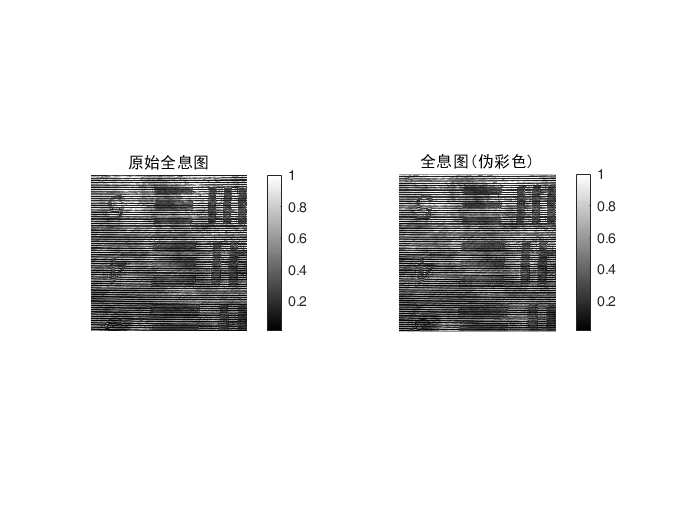


% 如果图像不是正方形，可以裁剪或调整
if N ~= M
    fprintf('警告: 图像不是正方形，将裁剪为正方形\n');
    min_dim = min(N, M);
    I = I(1:min_dim, 1:min_dim);
    N = min_dim;
    M = min_dim;
end

% 创建坐标网格
x = (-N/2:N/2-1)*dx;
[X, Y] = meshgrid(x, x);

%% =============================
% 3. 显示原始全息图
% =============================
figure;
subplot(1,2,1);
imshow(I, []);
title('原始全息图', 'FontName', 'SimHei');
colorbar;

subplot(1,2,2);
imagesc(I);
axis image off;
colormap gray;
title('全息图(伪彩色)', 'FontName', 'SimHei');
colorbar;


chuang =  hann(N) .* hann(N);

I = I.*chuang;

%% =============================
% 4. 2D FFT
% =============================
H = fftshift(fft2(I));
H_amp = abs(H);

%% =============================
% 5. 自动检测 +1 级（矩形滤波器）
% =============================
% 去掉中心直流区域（防止选到零级）
center = N/2 + 1;
mask_zero = zeros(N);
mask_zero(center-10:center+10, center-10:center+10) = 1;
H_amp_masked = H_amp;
H_amp_masked(mask_zero==1) = 0;

% 找频谱最大值 → +1 级
[~, idx] = max(H_amp_masked(:));
[v0, u0] = ind2sub([N, N], idx);
fprintf('自动检测 +1 级位置：u0=%d, v0=%d\n', u0, v0);

自动检测 +1 级位置：u0=257, v0=171


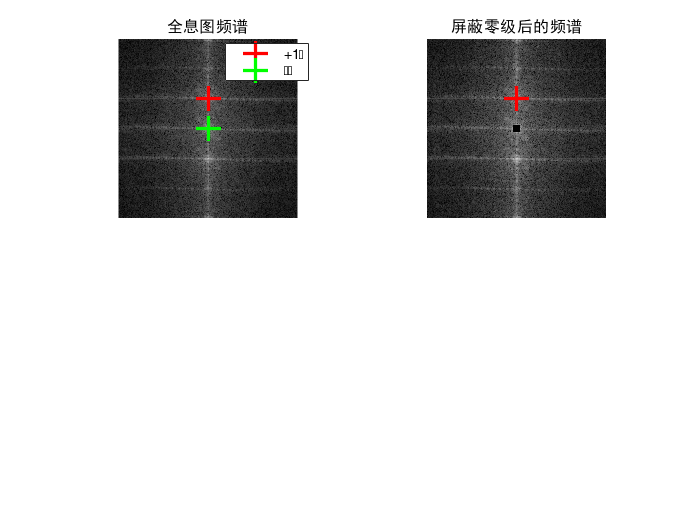


% 显示频谱
figure;
subplot(2,2,1);
imagesc(log(1+H_amp));
axis image off;
colormap gray;
title('全息图频谱', 'FontName', 'SimHei');
hold on;
plot(u0, v0, 'r+', 'MarkerSize', 15, 'LineWidth', 2);
plot(center, center, 'g+', 'MarkerSize', 15, 'LineWidth', 2);
legend('+1级', '零级', 'Location', 'best');

subplot(2,2,2);
imagesc(log(1+H_amp_masked));
axis image off;
colormap gray;
title('屏蔽零级后的频谱', 'FontName', 'SimHei');
hold on;
plot(u0, v0, 'r+', 'MarkerSize', 15, 'LineWidth', 2);

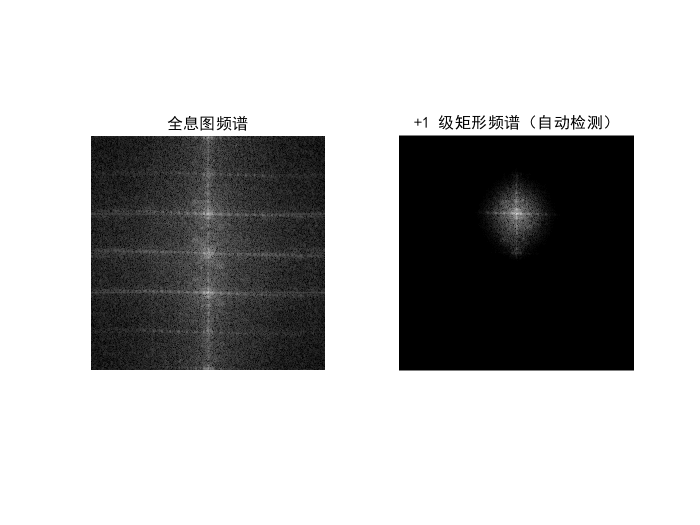



% -----------------------------
% 矩形滤波器
% -----------------------------
u = (1:N) - center;
v = (1:N) - center;
[U, V] = meshgrid(u, v);

% ----------- 高斯窗滤波器设计 -----------
sigma = 28;    % 频域高斯窗口宽度

G = exp(-((U-(u0-center)).^2 + (V-(v0-center)).^2) / (2*sigma^2));
Hf = H.*G; 
figure;
subplot(1,2,1);
imagesc(log(1+H_amp)); axis image off;
colormap gray;
title('全息图频谱','FontName','SimHei');

subplot(1,2,2);
imagesc(log(1+abs(Hf))); axis image off;
colormap gray;
title('+1 级矩形频谱（自动检测）','FontName','SimHei');

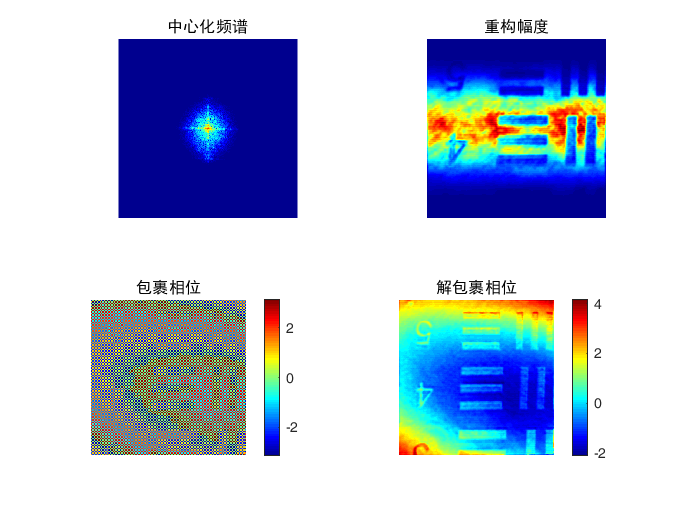


%% =============================
% 7. IFFT 重构复振幅
% =============================
% 计算精准移位量：将(u0,v0)移到频谱矩阵物理中心(center,center)
shift_x = center - u0;  % 列方向移位量（u轴）
shift_y = center - v0;  % 行方向移位量（v轴）

% 替代：用circshift实现频谱中心化（抛弃ifftshift）
% circshift(矩阵, [行移位量, 列移位量]) → 完美匹配u0/v0坐标
Hf_center = circshift(Hf, [shift_y, shift_x]);  

% IFFT重构复振幅（直接对中心化后的频谱操作）
U = ifft2(Hf_center);  

amp = abs(U);
phi_wrapped = angle(U);
%% =============================
% 8. 最小二乘相位解包裹（替换原相位解包裹）
% =============================
phi_unwrap = least_squares_unwrap(phi_wrapped);
figure;
subplot(2,2,1);
imagesc(log(1+abs(Hf_center)));axis image off;
colormap gray;
title('中心化频谱','FontName','SimHei');

subplot(2,2,2);
imagesc(amp); axis image off;
colormap gray;
title('重构幅度','FontName','SimHei');
subplot(2,2,3);
imagesc(phi_wrapped); axis image off;
colormap jet; colorbar;
title('包裹相位','FontName','SimHei');

subplot(2,2,4);
imagesc(phi_unwrap); axis image off;
colormap jet; colorbar;
title('解包裹相位','FontName','SimHei');

%% =============================
% 9. 倾斜平面校正
% =============================
% 使用背景区域拟合倾斜平面
% 创建背景掩模（假设物体在中心，边缘是背景）
background_mask = zeros(N);
border_width = 30; % 边缘宽度
background_mask(1:border_width, :) = 1;
background_mask(end-border_width+1:end, :) = 1;
background_mask(:, 1:border_width) = 1;
background_mask(:, end-border_width+1:end) = 1;

% 提取背景点的坐标和相位值
bg_points = find(background_mask);
bg_X = X(bg_points);
bg_Y = Y(bg_points);
bg_phi = phi_unwrap(bg_points);

% 最小二乘拟合平面：phi = a*x + b*y + c
A = [bg_X(:), bg_Y(:), ones(length(bg_X), 1)];
coeffs = A \ bg_phi(:); % 求解系数
a = coeffs(1);
b = coeffs(2);
c = coeffs(3);

% 计算拟合的倾斜平面
phi_tilt = a*X + b*Y + c;

% 从解包裹相位中减去倾斜平面
phi_corrected = phi_unwrap - phi_tilt;

% 方法2：使用整个图像拟合平面（作为对比）
A_full = [X(:), Y(:), ones(N*N, 1)];
coeffs_full = A_full \ phi_unwrap(:);
phi_tilt_full = coeffs_full(1)*X + coeffs_full(2)*Y + coeffs_full(3);
phi_corrected_full = phi_unwrap - phi_tilt_full;

%% =============================
% 10. 边缘裁剪
% =============================
crop_pixels = 40; % 裁剪边缘像素数
phi_cropped = phi_corrected(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);
phi_cropped_full = phi_corrected_full(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);
X_cropped = X(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);
Y_cropped = Y(crop_pixels+1:end-crop_pixels, crop_pixels+1:end-crop_pixels);


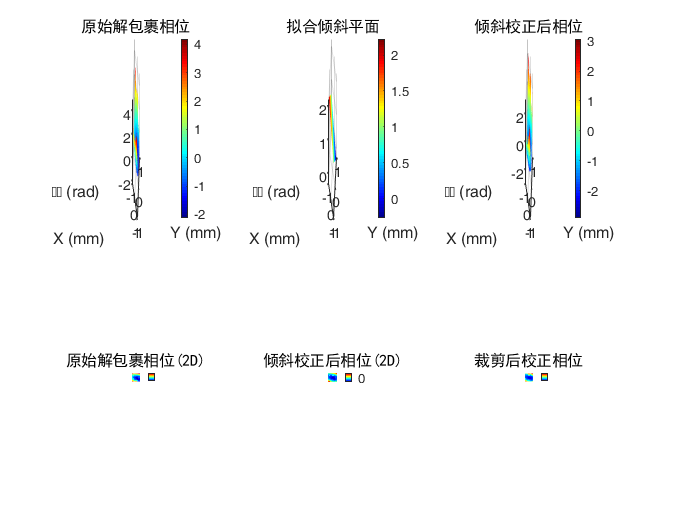

%% =============================
% 11. 可视化结果
% =============================
% 原始解包裹相位（三维）
figure;
subplot(2,3,1);
surf(X*1000, Y*1000, phi_unwrap, 'EdgeColor', 'none');
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
title('原始解包裹相位','FontName','SimHei');
colormap jet; colorbar; view(30, 40); grid on;

subplot(2,3,2);
surf(X*1000, Y*1000, phi_tilt, 'EdgeColor', 'none');
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
title('拟合倾斜平面','FontName','SimHei');
colormap jet; colorbar; view(30, 40); grid on;

subplot(2,3,3);
surf(X*1000, Y*1000, phi_corrected, 'EdgeColor', 'none');
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
title('倾斜校正后相位','FontName','SimHei');
colormap jet; colorbar; view(30, 40); grid on;

subplot(2,3,4);
imagesc(phi_unwrap); axis image off;
colormap jet; colorbar;
title('原始解包裹相位(2D)','FontName','SimHei');

subplot(2,3,5);
imagesc(phi_corrected); axis image off;
colormap jet; colorbar;
title('倾斜校正后相位(2D)','FontName','SimHei');

subplot(2,3,6);
imagesc(phi_cropped); axis image off;
colormap jet; colorbar;
title('裁剪后校正相位','FontName','SimHei');

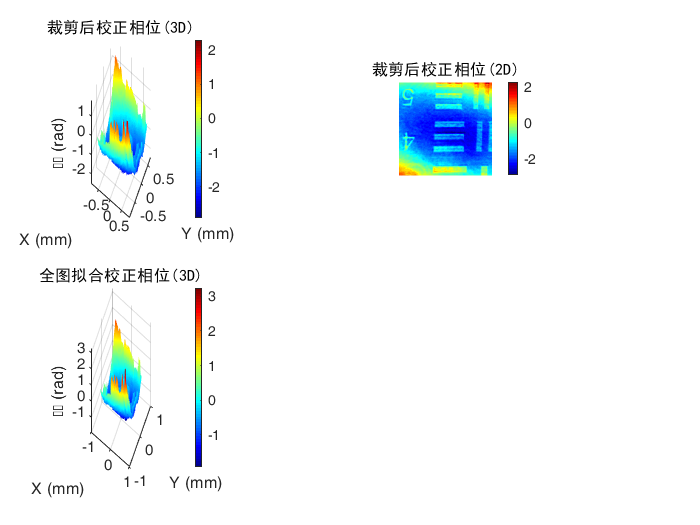


% 裁剪后的三维显示
figure;
subplot(2,2,1);
surf(X_cropped*1000, Y_cropped*1000, phi_cropped, 'EdgeColor', 'none');
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
title('裁剪后校正相位(3D)','FontName','SimHei');
colormap jet; colorbar; view(30, 40); grid on;

subplot(2,2,2);
imagesc(phi_cropped); axis image off;
colormap jet; colorbar;
title('裁剪后校正相位(2D)','FontName','SimHei');

subplot(2,2,3);
surf(X_cropped*1000, Y_cropped*1000, phi_cropped_full, 'EdgeColor', 'none');
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('相位 (rad)');
title('全图拟合校正相位(3D)','FontName','SimHei');
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    colormap jet; colorbar; view(30, 40); grid on;